# Project: Corrupting a Pilot

Wireless Communications, Spring 2025

Prof. Sundeep Rangan

Authors: Aritra Roy (ar9010), Hakan Gulec (hg2918)

**1 Problem Formulation**

Pilot-based channel estimation is the workhorse of almost every wireless standard, yet it exposes a critical weakness: if even a single pilot symbol is corrupted by an adversary, the resulting channel estimate may damage an entire block of data. The question addressed in this project is simple to state but subtle to answer: **What is the worst-case capacity when a power-bounded adversary is allowed to corrupt a limited portion of each fading block?**

We adopt a scalar block-fading model. Each coherence block contains $L$ QPSK symbols that all experience a common Rayleigh gain $h$. A random number of those symbols, denoted $L_p$, are reserved for pilots; $L_p$ is drawn uniformly from the set $\left\lbrace 1,2,\ldotp \ldotp \ldotp ,L-1\right\rbrace$ at the start of every block. The transmitter and receiver know the drawn value, while the adversary only knows that the pilots are grouped contiguously at the beginning of the block. The adversary can add a noise into the first $L_a$ symbols; its total budget per block is $P_{\textrm{adv},\textrm{tot}}$, so each of the $L_a$ targets receives the same energy $P_{\textrm{adv},\textrm{tot}} /L_a$. Our goal is to quantify the resulting bit-error rate, to derive and validate the worst-case bounds, and to translate those error statistics into a lower-bound on the achievable rate.

**2 Approach and Design**

The starting point is a baseline MATLAB simulation that generates IID Rayleigh blocks, maps random information bits to QPSK, embeds the chosen pilot prefix, and passes the resulting vector through AWGN.  Channel estimation is performed by averaging all pilot observations and dividing by the known pilot value.  A hard-decision minimum-distance detector then demodulates the equalised data symbols. In other words, a block fading SISO channel is considered through which the data is transmitted in groups of $L$ symbols. channel gain is constant in each block and i.i.d. between blocks.


$$r\left\lbrack k,j\right\rbrack =h\left\lbrack k\right\rbrack x\left\lbrack k,j\right\rbrack +w\left\lbrack k,j\right\rbrack ,j=0,\ldotp \ldotp \ldotp ,L-1$$


Here, $r$ is the received symbols over each block, $h\left\lbrack k\right\rbrack$ is the channel in each block $k$, and $w$ is the Gaussian noise.

**3 Baseline System Simulation with No Adversary**

This script is to realize the baseline system for block-fading SISO channel.

% This script is a simulation for baseline block-fading SISO channel

clear;
clc;
close all;


The number of blocks is set to $1000$ and number of symbols per block is $8$. SNR values are sweeped from $0$ to $20$ dB. QPSK modulation is used so that the number of bits per symbol is $2$.

%% Parameter Setup for the Simulation


% Define the parameters
number_of_blocks    = 1000        ;
l_symbols_per_block = 10          ;
snr_db              = 0:2:20      ;
m_qpsk              = 4           ;
k_bits_per_symbol   = log2(m_qpsk);

QPSK modulation is used.

%% QPSK Symbol Mapping


% Implement QPSK symbol mapping
qpsk_map = exp(1j * (pi / 4 + (0:(m_qpsk - 1)) * pi / 2));

The simulation to compute BER is performed. The pilot symbol is located in the first index of each block.

%% Loop for Simulation


% Create variable to store BER
bit_error_rate = zeros(size(snr_db));

% Create the loop for simulating SISO block-fading channel
for snr_idx = 1:length(snr_db)

    % Convert SNR from dB into linear scale
    snr_linear = 10 ^ (snr_db(snr_idx) / 10);

    % Define noise variance
    noise_variance = 1 / snr_linear;

    % Create variable to count the number of total bits
    number_of_bit_errors = 0;

    % Create variable to count the bit errors 
    number_of_total_bits = 0;

    % Loop over the blocks
    for block_idx = 1:number_of_blocks
    
        % Generate one fading coefficient per block - Rayleigh fading
        h = (randn + 1j * randn) / sqrt(2);

        % Define the pilot symbol - first position in each block
        pilot_symbol = 1 + 0j;

        % The received pilot symbol
        rx_pilot = h * pilot_symbol + sqrt(noise_variance / 2) * ...
            (randn + 1j * randn);

        % Estimate the channel
        h_estimate = rx_pilot / pilot_symbol;

        % Generate data bits 
        data_bits = randi([0 1], k_bits_per_symbol * ...
            (l_symbols_per_block - 1), 1);

        % Reshape the data bits
        data_bits_reshaped = reshape(data_bits, k_bits_per_symbol, []).';

        % Define the index variable to track the data symbols
        data_symbol_idx = zeros(size(data_bits_reshaped, 1), 1);
        
        % Keep the indices of the symbols
        for i = 1:k_bits_per_symbol

            data_symbol_idx = data_symbol_idx + data_bits_reshaped(:, i)...
                * 2 ^ (k_bits_per_symbol - i);
        
        end
        
        % Create the data symbols
        data_symbols = qpsk_map(data_symbol_idx + 1).';

        % Transmit the pilot and data symbols
        tx_block = [pilot_symbol; data_symbols];

        % Introduce noise 
        noise = sqrt(noise_variance / 2) * (randn(l_symbols_per_block, 1)...
            + 1j * randn(l_symbols_per_block, 1));
        
        % Obtain the received block
        rx_block = h * tx_block + noise;

        % Equalize the received data symbols 
        rx_data = reshape(rx_block(2:end), [], 1);
        rx_eq   = rx_data / h_estimate;

        % Demodulate the symbols using minimum distance 
        distances = abs(rx_eq - reshape(qpsk_map, 1, []));
        [~, demod_idx] = min(distances, [], 2);           

        % Convert symbol indices to bits
        rx_bits_matrix = zeros(length(demod_idx), k_bits_per_symbol);
        
        % Obtain the received bits from symbol
        for i = 1:k_bits_per_symbol
        
            rx_bits_matrix(:, i) = bitget(demod_idx - 1,...
                k_bits_per_symbol - i + 1);
        
        end

        % Obtain the received bits
        rx_bits = reshape(rx_bits_matrix.', [], 1);  

        % Count the errors and total number of the bits
        number_of_bit_errors = number_of_bit_errors + sum(rx_bits ~= data_bits);
        number_of_total_bits = number_of_total_bits + length(data_bits);
    
    end

    % Calculate the bit error rate
    bit_error_rate(snr_idx) = number_of_bit_errors / number_of_total_bits;

end

The resulted BER vs. SNR is displayed in the figure below.

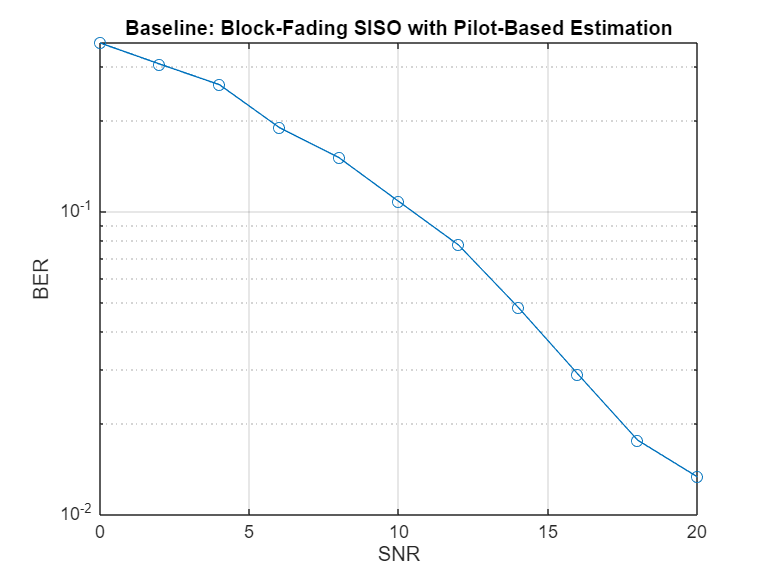

%% Display the results


% Display the BER vs SNR
figure('Name', 'BER vs SNR', 'NumberTitle', 'off');
semilogy(snr_db, bit_error_rate, '-o');
grid on
xlabel('SNR'); 
ylabel('BER');
title('Baseline: Block-Fading SISO with Pilot-Based Estimation');

**4 System with Adversary**

An adversary $z$ is considered:


$$r\left\lbrack k,j\right\rbrack =h\left\lbrack k\right\rbrack x\left\lbrack k,j\right\rbrack +w\left\lbrack k,j\right\rbrack +z\left\lbrack k,j\right\rbrack ,\;j=0,\ldotp \ldotp \ldotp ,L-1$$


$z\left\lbrack k,j\right\rbrack$ is an adversary with some bound: $E|z\left\lbrack k,j\right\rbrack |^2 <\epsilon$.

To model the adversary we insert an additive term immediately after the AWGN stage.

**5 System with Adversary - Simple Introduction**

We modified the baseline system to introduce adversary. Here, the number of symbols is set to $6$ to better see the effect of the adversary. The rest of the parameters are the same.

clear;
clc;
close all;


%% Parameter Setup for the Simulation


% Define the parameters
count_blocks    = 10000       ;     % Number of blocks
l_sym_per_block = 6           ;     % Number of symbols per block
snr_db          = 0:2:20      ;     % SNR values
m_qpsk          = 4           ;     % QPSK modulation
k_bits_per_sym  = log2(m_qpsk);     % Number of bits per symbol
variance_adv    = 0.1         ;     % Power bound for adversary

QPSK symbol mapping is used again.

%% QPSK Symbol Mapping


% Implement QPSK symbol mapping
qpsk_map = exp(1j * (pi / 4 + (0:(m_qpsk - 1)) * pi / 2));

For this simulation, the mechanism of the adversary is a follows:

- Blind adversary is introduced to corrupt one random symbol in each block. 

- We first assumed that adversary does not know pilot symbols are in the first position of each block.

- If adversary hits the correct symbol, then the damage is higher.

%% Loop for Simulation


% Create variable to store BER with no adversary
bit_error_rate = zeros(size(snr_db));

% Create variable to store BER with adversary
bit_error_rate_adv = zeros(size(snr_db));

% Create variable to store the capacity
capacity = zeros(size(snr_db));

% Create the loop for simulating SISO block-fading channel
for snr_idx = 1:length(snr_db)

    % Convert SNR from dB into linear scale
    snr_linear = 10 ^ (snr_db(snr_idx) / 10);

    % Define noise variance
    noise_variance = 1 / snr_linear;

    % Create variable to count the number of total bits
    count_bit_errors = 0;

    % Create variable to count the bit errors 
    count_total_bits = 0;

    % Create variable to count the bit errors with adversary
    count_bit_errors_adv = 0;

    % Create variable to store the number of pilot symbols corrupted
    count_pilot_corrupted = 0;

    % Loop over the blocks
    for block_idx = 1:count_blocks
    
        % Generate one fading coefficient per block - Rayleigh fading
        h = (randn + 1j * randn) / sqrt(2);

        % Define the pilot symbol - first position in each block
        pilot_sym = 1 + 0j;

        % Generate data bits 
        data_bits = randi([0 1], k_bits_per_sym * ...
            (l_sym_per_block - 1), 1);

        % Reshape the data bits
        data_bits_reshaped = reshape(data_bits, k_bits_per_sym, []).';

        % Define the index variable to track the data symbols
        data_sym_idx = zeros(size(data_bits_reshaped, 1), 1);
        
        % Keep the indices of the symbols
        for i = 1:k_bits_per_sym

            data_sym_idx = data_sym_idx + data_bits_reshaped(:, i)...
                * 2 ^ (k_bits_per_sym - i);
        
        end
        
        % Create the data symbols
        data_syms = qpsk_map(data_sym_idx + 1).';

        % Transmit the pilot and data symbols
        tx_block = [pilot_sym; data_syms];

        % Introduce noise 
        noise = sqrt(noise_variance / 2) * (randn(l_sym_per_block, 1)...
            + 1j * randn(l_sym_per_block, 1));
        
        % Obtain the received block
        rx_block = h * tx_block + noise;

        % The received pilot symbol before adversary attempts
        rx_pilot = rx_block(1);

        % Create variable to compare the case between with adversary and
        % with no adversary
        rx_block_adv = rx_block;

        % Introduce the blind adversary corrupts one random symbol
        corruption_idx = randi(l_sym_per_block);
        rx_block_adv(corruption_idx) = rx_block_adv(corruption_idx) + ...
            sqrt(variance_adv) * exp(1j * 2 * pi * rand);

        % Check if the pilot symbol is hit
        if corruption_idx == 1

            count_pilot_corrupted = count_pilot_corrupted + 1;
        
        end

        % Estimate the channel with no adversary
        h_estimate = rx_pilot / pilot_sym;

        % Equalize the received data symbols 
        rx_data = reshape(rx_block(2:end), [], 1);
        rx_eq   = rx_data / h_estimate;

        % Demodulate the symbols using minimum distance 
        distances = abs(rx_eq - reshape(qpsk_map, 1, []));
        [~, demod_idx] = min(distances, [], 2);           

        % Convert symbol indices to bits
        rx_bits_matrix = zeros(length(demod_idx), k_bits_per_sym);
        
        % Obtain the received bits from symbol
        for i = 1:k_bits_per_sym
        
            rx_bits_matrix(:, i) = bitget(demod_idx - 1,...
                k_bits_per_sym - i + 1);
        
        end

        % Obtain the received bits
        rx_bits = reshape(rx_bits_matrix.', [], 1);  

        % Count the errors and total number of the bits
        count_bit_errors = count_bit_errors + sum(rx_bits ~= data_bits);
        count_total_bits = count_total_bits + length(data_bits);
    
        % Estimate the channel with adversary
        h_estimate_adv = rx_block_adv(1) / pilot_sym;

        % Equalize the received data symbols 
        rx_data_adv = reshape(rx_block_adv(2:end), [], 1);
        rx_eq_adv   = rx_data_adv / h_estimate_adv;

        % Demodulate the symbols using minimum distance 
        distances_adv = abs(rx_eq_adv - reshape(qpsk_map, 1, []));
        [~, demod_idx_adv] = min(distances_adv, [], 2);           

        % Convert symbol indices to bits
        rx_bits_matrix_adv = zeros(length(demod_idx_adv), k_bits_per_sym);
        
        % Obtain the received bits from symbol
        for i = 1:k_bits_per_sym
        
            rx_bits_matrix_adv(:, i) = bitget(demod_idx_adv - 1,...
                k_bits_per_sym - i + 1);
        
        end

        % Obtain the received bits
        rx_bits_adv = reshape(rx_bits_matrix_adv.', [], 1);  

        % Count the errors 
        count_bit_errors_adv = count_bit_errors_adv + sum(rx_bits_adv ~= data_bits);


    end

    % Calculate the bit error rate with no adversary
    bit_error_rate(snr_idx) = count_bit_errors / count_total_bits;

    % Calculate the bit error rate with adversary
    bit_error_rate_adv(snr_idx) = count_bit_errors_adv / ...
        count_total_bits;

end


The resulted BER vs. SNR is displayed in the figure below.

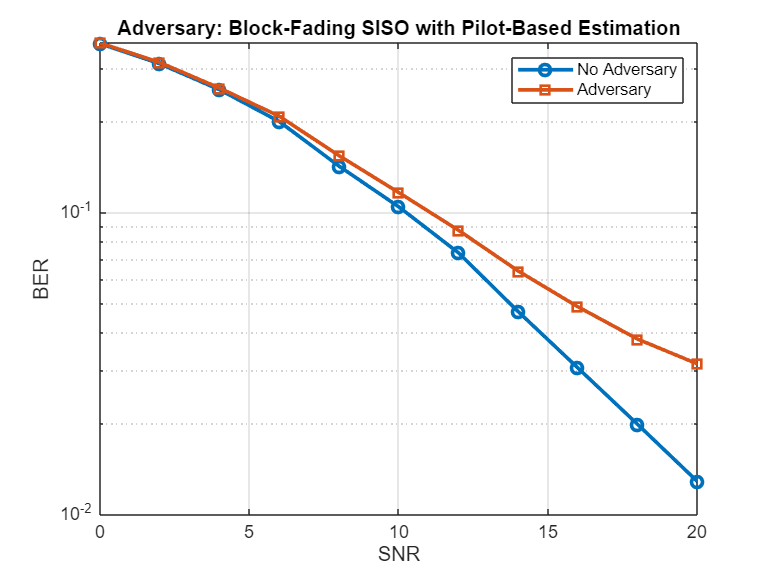

%% Display the results


% Display the BER vs SNR
figure('Name', 'BER vs SNR', 'NumberTitle', 'off');
semilogy(snr_db, bit_error_rate, '-o', 'LineWidth', 2);
hold on
semilogy(snr_db, bit_error_rate_adv, '-s', 'LineWidth', 2);
grid on
legend('No Adversary', 'Adversary');
xlabel('SNR'); 
ylabel('BER');
title('Adversary: Block-Fading SISO with Pilot-Based Estimation');

% Print pilot corruption probability 
fprintf('Pilot was hit %.2f%% of the time by adversary\n', ...
    100 * count_pilot_corrupted / (count_blocks * length(snr_db)));

Pilot was hit 1.52% of the time by adversary


**6 System with Adversary - A More Realistic Approach**

In the real wireless communication settings, usually first couple of slots of each block are reserved for pilot symbols. Thus, it is more realistic for adversary to know the pilots are at the beginning of each block, but to be fair, it does not know how many pilot symbols are used. Again, to model the adversary we insert an additive term immediately after the AWGN stage. Let $L$ be the number of symbols in each block. Let $L_p$ and $L_c$ denote the number of pilot symbols and number of communication symbols in each block. $L_a$ is the number of symbols adversary tries to corrupt, and it holds $L_a ~U\left(1,L-1\right)$. Given $L_a$ and the total power bound for adversary $P_{\textrm{adv},\textrm{tot}}$ the script computes the per-symbol corruption amplitude $\sqrt{P_{\textrm{adv},\textrm{tot}} /L_a }$ and adds a phasor with random argument to symbols $1,\ldotp \ldotp \ldotp ,L_a$. Because the adversary does not know $L_p$ in advance it may or may not hit the pilot field; the probability of hitting exactly $k$ pilot symbols in a block is $\Pr \left\lbrack k\right\rbrack =\Pr \left\lbrack L_p \ge k\right\rbrack -\Pr \left\lbrack L_p \ge k+1\right\rbrack$, but in practive the Monte-Carlo loop simply records how often any pilot symbol is altered. [Fix the probability definition]

Two theoretical reference points guide the interpretation of the results.  First, if the adversary has unbounded power, then every corrupted symbol becomes completely unreliable; the best the decoder can do in that slot is guess, so each corrupted bit contributes a probability one-half error floor.  This yields the lower-bound 


$$P_e \ge \frac{L_a }{2L}$$


Second, the clipped-LLR capacity formula of Ying et al. for a binary memoryless channel with flip-fraction $\delta =L_a /L$ gives an upper-bound on the rate that any scheme can achieve in the worst case. Although their derivation assumes a symbol-symmetric jammer rather than an energy-bounded one, it serves as a useful benchmark. The earlier work of Sarwate on myopic AVCs provides additional context for why such minimax constructions are tight when the attacker has limited side information.

**7 Simulation**

clear;
clc;
close all;


%% Parameter Setup for the Simulation


% Define the parameters
count_blocks        = 10000       ;     % Number of blocks
l_sym_per_block     = 10          ;     % Number of symbols per block
l_p_pilot_per_block = 3           ;     % Number of pilot symbols per block
snr_db              = 0:2:20      ;     % SNR values
m_qpsk              = 4           ;     % QPSK modulation
k_bits_per_sym      = log2(m_qpsk);     % Number of bits per symbol
variance_adv        = 1.0         ;     % Power bound for adversary

% Define the communication symbols per block
l_c_data_per_block = l_sym_per_block - l_p_pilot_per_block;

%% QPSK Symbol Mapping


% Implement QPSK symbol mapping
qpsk_map = exp(1j * (pi / 4 + (0:(m_qpsk - 1)) * pi / 2));

%% Loop for Simulation


% Create variable to store BER with no adversary
bit_error_rate = zeros(size(snr_db));

% Create variable to store BER with adversary
bit_error_rate_adv = zeros(size(snr_db));

% Create variable to store the capacity
capacity = zeros(size(snr_db));

% Create the loop for simulating SISO block-fading channel
for snr_idx = 1:length(snr_db)

    % Convert SNR from dB into linear scale
    snr_linear = 10 ^ (snr_db(snr_idx) / 10);

    % Define noise variance
    noise_variance = 1 / snr_linear;

    % Create variable to count the number of total bits
    count_bit_errors = 0;

    % Create variable to count the bit errors 
    count_total_bits = 0;

    % Create variable to count the bit errors with adversary
    count_bit_errors_adv = 0;

    % Create variable to store the number of pilot symbols corrupted
    count_pilot_corrupted = 0;

    % Loop over the blocks
    for block_idx = 1:count_blocks
    
        % Generate one fading coefficient per block - Rayleigh fading
        h = (randn + 1j * randn) / sqrt(2);

        % Define pilot symbol indices
        pilot_idx = 1:l_p_pilot_per_block;

        % Define data symbol indices
        data_idx = (l_p_pilot_per_block + 1):l_sym_per_block;

        % Define the pilot symbol - first position in each block
        pilot_sym = 1 + 0j;

        % Generate data bits 
        data_bits = randi([0 1], k_bits_per_sym * l_c_data_per_block, 1);

        % Reshape the data bits
        data_bits_reshaped = reshape(data_bits, k_bits_per_sym, []).';

        % Define the index variable to track the data symbols
        data_sym_idx = zeros(size(data_bits_reshaped, 1), 1);
        
        % Keep the indices of the symbols
        for i = 1:k_bits_per_sym

            data_sym_idx = data_sym_idx + data_bits_reshaped(:, i)...
                * 2 ^ (k_bits_per_sym - i);
        
        end
        
        % Create the data symbols
        data_syms = qpsk_map(data_sym_idx + 1).';

        % Transmit the pilot and data symbols
        tx_block            = zeros(l_sym_per_block, 1);
        tx_block(pilot_idx) = pilot_sym                ;
        tx_block(data_idx)  = data_syms                ;

        % Introduce noise 
        noise = sqrt(noise_variance / 2) * (randn(l_sym_per_block, 1)...
            + 1j * randn(l_sym_per_block, 1));
        
        % Obtain the received block
        rx_block = h * tx_block + noise;

        % The received pilot symbol before adversary attempts
        rx_pilot_syms = rx_block(pilot_idx);

        % Create variable to compare the case between with adversary and
        % with no adversary
        rx_block_adv = rx_block;

        % Decide how many symbols to corrupt - U(1, L - 1)
        l_a_adversaried_sym = randi([1, l_sym_per_block - 1]);

        % Introduce the blind adversary corrupts symbols
        rx_block_adv(1:l_a_adversaried_sym) = ...
            rx_block_adv(1:l_a_adversaried_sym) + sqrt(variance_adv / ...
            l_a_adversaried_sym) * exp(1j * 2 * pi * rand);

        % Estimate the channel with no adversary
        h_estimate = mean(rx_pilot_syms) / pilot_sym;

        % Equalize the received data symbols 
        rx_data = reshape(rx_block((l_p_pilot_per_block + 1):end), [], 1);
        rx_eq   = rx_data / h_estimate;

        % Demodulate the symbols using minimum distance 
        distances = abs(rx_eq - reshape(qpsk_map, 1, []));
        [~, demod_idx] = min(distances, [], 2);           

        % Convert symbol indices to bits
        rx_bits_matrix = zeros(length(demod_idx), k_bits_per_sym);
        
        % Obtain the received bits from symbol
        for i = 1:k_bits_per_sym
        
            rx_bits_matrix(:, i) = bitget(demod_idx - 1,...
                k_bits_per_sym - i + 1);
        
        end

        % Obtain the received bits
        rx_bits = reshape(rx_bits_matrix.', [], 1);  

        % Count the errors and total number of the bits
        count_bit_errors = count_bit_errors + sum(rx_bits ~= data_bits);
        count_total_bits = count_total_bits + length(data_bits);
    
        % Estimate the channel with adversary
        h_estimate_adv = mean(rx_block_adv(pilot_idx)) / pilot_sym;

        % Equalize the received data symbols 
        rx_data_adv = reshape(rx_block_adv((l_p_pilot_per_block + 1):...
            end), [], 1);
        rx_eq_adv = rx_data_adv / h_estimate_adv;

        % Demodulate the symbols using minimum distance 
        distances_adv = abs(rx_eq_adv - reshape(qpsk_map, 1, []));
        [~, demod_idx_adv] = min(distances_adv, [], 2);           

        % Convert symbol indices to bits
        rx_bits_matrix_adv = zeros(length(demod_idx_adv), k_bits_per_sym);
        
        % Obtain the received bits from symbol
        for i = 1:k_bits_per_sym
        
            rx_bits_matrix_adv(:, i) = bitget(demod_idx_adv - 1,...
                k_bits_per_sym - i + 1);
        
        end

        % Obtain the received bits
        rx_bits_adv = reshape(rx_bits_matrix_adv.', [], 1);  

        % Count the errors 
        count_bit_errors_adv = count_bit_errors_adv + sum(rx_bits_adv ~= data_bits);


    end

    % Calculate the bit error rate with no adversary
    bit_error_rate(snr_idx) = count_bit_errors / count_total_bits;

    % Calculate the bit error rate with adversary
    bit_error_rate_adv(snr_idx) = count_bit_errors_adv / ...
        count_total_bits;

end


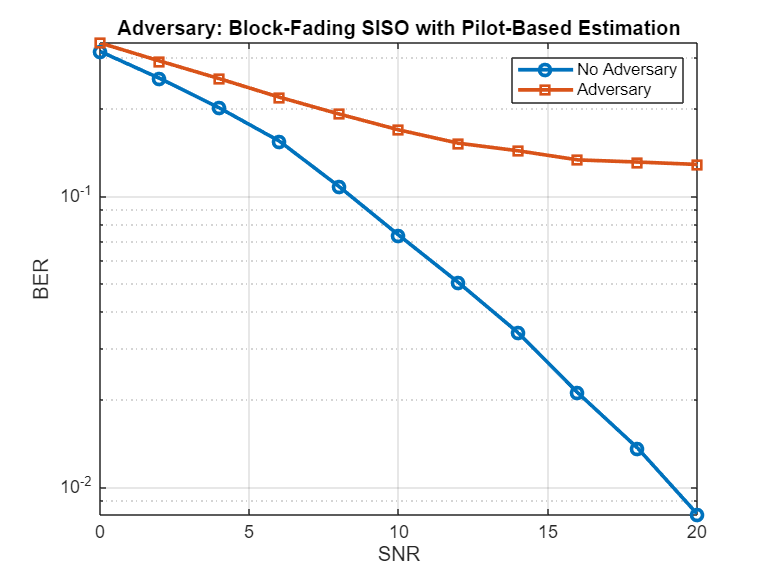

% Display the BER vs SNR
figure('Name', 'BER vs SNR', 'NumberTitle', 'off');
semilogy(snr_db, bit_error_rate, '-o', 'LineWidth', 2);
hold on
semilogy(snr_db, bit_error_rate_adv, '-s', 'LineWidth', 2);
grid on
legend('No Adversary', 'Adversary');
xlabel('SNR'); 
ylabel('BER');
title('Adversary: Block-Fading SISO with Pilot-Based Estimation');

%%checking the effect of L_a on pilot curruption performance

clear;
clc;
close all;

%% Parameter Setup for the Simulation

% Define the parameters
count_blocks        = 10000       ;     % Number of blocks
l_sym_per_block     = 100          ;     % Number of symbols per block
l_p_pilot_per_block_array = [1:1:l_sym_per_block-1] ;     % Number of pilot symbols per block
%snr_db              = 10:10:20     ;     % SNR values
snr_db              = 10:5:20     ;     % SNR values
m_qpsk              = 4           ;     % QPSK modulation
k_bits_per_sym      = log2(m_qpsk);     % Number of bits per symbol
variance_adv        = 1         ;     % Power bound for adversary

% Define the communication symbols per block

%% QPSK Symbol Mapping

% Implement QPSK symbol mapping
qpsk_map = exp(1j * (pi / 4 + (0:(m_qpsk - 1)) * pi / 2));

%% Loop for Simulation


% Create variable to store BER with no adversary
bit_error_rate = zeros(length(snr_db), length(l_p_pilot_per_block_array));

% Create variable to store BER with adversary
bit_error_rate_adv = zeros(length(snr_db), length(l_p_pilot_per_block_array));

relative_ber_change = zeros(length(snr_db), length(l_p_pilot_per_block_array));

% Create variable to store the capacity
capacity = zeros(size(snr_db));

% Create the loop for simulating SISO block-fading channel
for snr_idx = 1:length(snr_db)

    % Convert SNR from dB into linear scale
    snr_linear = 10 ^ (snr_db(snr_idx) / 10);

    % Define noise variance
    noise_variance = 1 / snr_linear;

    % Create variable to count the number of total bits
    count_bit_errors = 0;

    % Create variable to count the bit errors 
    count_total_bits = 0;

    % Create variable to count the bit errors with adversary
    count_bit_errors_adv = 0;

    % Create variable to store the number of pilot symbols corrupted
    count_pilot_corrupted = 0;

    for pilot_array_idx = 1:length(l_p_pilot_per_block_array)
        l_p_pilot_per_block = l_p_pilot_per_block_array(pilot_array_idx);
        l_c_data_per_block = l_sym_per_block - l_p_pilot_per_block; %change this later

        % Loop over the blocks
        for block_idx = 1:count_blocks
        
            % Generate one fading coefficient per block - Rayleigh fading
            h = (randn + 1j * randn) / sqrt(2);
    
            % Define pilot symbol indices
            pilot_idx = 1:l_p_pilot_per_block;
    
            % Define data symbol indices
            data_idx = (l_p_pilot_per_block + 1):l_sym_per_block;
    
            % Define the pilot symbol - first position in each block
            pilot_sym = 1 + 0j;
    
            % Generate data bits 
            data_bits = randi([0 1], k_bits_per_sym * l_c_data_per_block, 1);
    
            % Reshape the data bits
            data_bits_reshaped = reshape(data_bits, k_bits_per_sym, []).';
    
            % Define the index variable to track the data symbols
            data_sym_idx = zeros(size(data_bits_reshaped, 1), 1);
            
            % Keep the indices of the symbols
            for i = 1:k_bits_per_sym
    
                data_sym_idx = data_sym_idx + data_bits_reshaped(:, i)...
                    * 2 ^ (k_bits_per_sym - i);
            
            end
            
            % Create the data symbols
            data_syms = qpsk_map(data_sym_idx + 1).';
    
            % Transmit the pilot and data symbols
            tx_block            = zeros(l_sym_per_block, 1);
            tx_block(pilot_idx) = pilot_sym                ;
            tx_block(data_idx)  = data_syms                ;
    
            % Introduce noise 
            noise = sqrt(noise_variance / 2) * (randn(l_sym_per_block, 1)...
                + 1j * randn(l_sym_per_block, 1));
            
            % Obtain the received block
            rx_block = h * tx_block + noise;
    
            % The received pilot symbol before adversary attempts
            rx_pilot_syms = rx_block(pilot_idx);
    
            % Create variable to compare the case between with adversary and
            % with no adversary
            rx_block_adv = rx_block;
    
            % Decide how many symbols to corrupt - U(1, L - 1)
            l_a_adversaried_sym = randi([1, l_sym_per_block - 1]);
    
            % Introduce the blind adversary corrupts symbols
            rx_block_adv(1:l_a_adversaried_sym) = ...
                rx_block_adv(1:l_a_adversaried_sym) + sqrt(variance_adv / ...
                l_a_adversaried_sym) * exp(1j * 2 * pi * rand);
    
            % Estimate the channel with no adversary
            h_estimate = mean(rx_pilot_syms) / pilot_sym;
    
            % Equalize the received data symbols 
            rx_data = reshape(rx_block((l_p_pilot_per_block + 1):end), [], 1);
            rx_eq   = rx_data / h_estimate;
    
            % Demodulate the symbols using minimum distance 
            distances = abs(rx_eq - reshape(qpsk_map, 1, []));
            [~, demod_idx] = min(distances, [], 2);           
    
            % Convert symbol indices to bits
            rx_bits_matrix = zeros(length(demod_idx), k_bits_per_sym);
            
            % Obtain the received bits from symbol
            for i = 1:k_bits_per_sym
            
                rx_bits_matrix(:, i) = bitget(demod_idx - 1,...
                    k_bits_per_sym - i + 1);
            
            end
    
            % Obtain the received bits
            rx_bits = reshape(rx_bits_matrix.', [], 1);  
    
            % Count the errors and total number of the bits
            count_bit_errors = count_bit_errors + sum(rx_bits ~= data_bits);
            count_total_bits = count_total_bits + length(data_bits);
        
            % Estimate the channel with adversary
            h_estimate_adv = mean(rx_block_adv(pilot_idx)) / pilot_sym;
    
            % Equalize the received data symbols 
            rx_data_adv = reshape(rx_block_adv((l_p_pilot_per_block + 1):...
                end), [], 1);
            rx_eq_adv = rx_data_adv / h_estimate_adv;
    
            % Demodulate the symbols using minimum distance 
            distances_adv = abs(rx_eq_adv - reshape(qpsk_map, 1, []));
            [~, demod_idx_adv] = min(distances_adv, [], 2);           
    
            % Convert symbol indices to bits
            rx_bits_matrix_adv = zeros(length(demod_idx_adv), k_bits_per_sym);
            
            % Obtain the received bits from symbol
            for i = 1:k_bits_per_sym
            
                rx_bits_matrix_adv(:, i) = bitget(demod_idx_adv - 1,...
                    k_bits_per_sym - i + 1);
            
            end
    
            % Obtain the received bits
            rx_bits_adv = reshape(rx_bits_matrix_adv.', [], 1);  
    
            % Count the errors 
            count_bit_errors_adv = count_bit_errors_adv + sum(rx_bits_adv ~= data_bits);
    
    
        end
    
        % Calculate the bit error rate with no adversary
        bit_error_rate(snr_idx, pilot_array_idx) = count_bit_errors / count_total_bits;
    
        % Calculate the bit error rate with adversary
        bit_error_rate_adv(snr_idx, pilot_array_idx) = count_bit_errors_adv / ...
            count_total_bits;

        relative_ber_change(snr_idx, pilot_array_idx) = (bit_error_rate_adv(snr_idx, pilot_array_idx) - bit_error_rate(snr_idx, pilot_array_idx))/bit_error_rate(snr_idx, pilot_array_idx);

    end

end

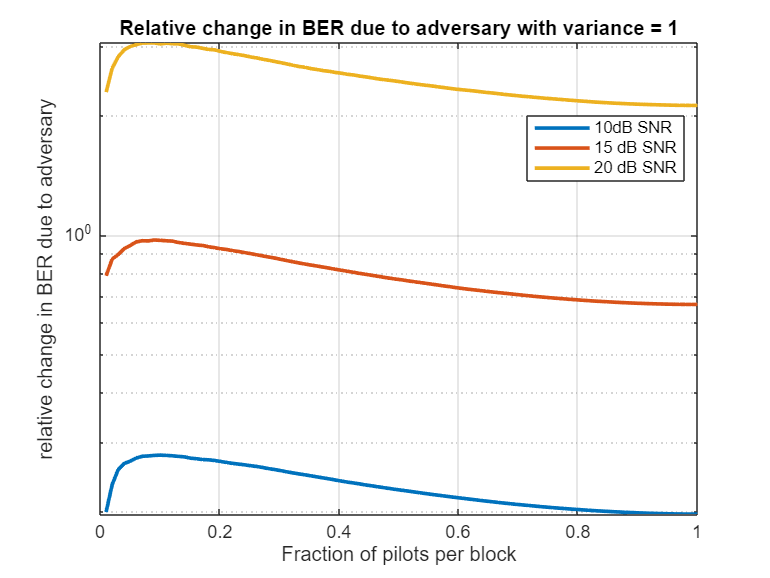

%plot section

figure();
semilogy(l_p_pilot_per_block_array/length(l_p_pilot_per_block_array), relative_ber_change(1, :), '-', 'LineWidth', 2); hold on
semilogy(l_p_pilot_per_block_array/length(l_p_pilot_per_block_array), relative_ber_change(2, :), '-', 'LineWidth', 2); 
semilogy(l_p_pilot_per_block_array/length(l_p_pilot_per_block_array), relative_ber_change(3, :), '-', 'LineWidth', 2); 
grid on
legend('10dB SNR', '15 dB SNR', '20 dB SNR');
xlabel('Fraction of pilots per block'); ylabel('relative change in BER due to adversary');
title('Relative change in BER due to adversary with variance = 1');
hold off

legend(["10dB SNR", "15 dB SNR", "20 dB SNR"], "Position", [0.6867 0.6875 0.2000, 0.1119]);

**8 Conclusion**

All logic is divided into five functions—block generator, modulator, channel, adversary, and receiver. The study confirms that a power-bounded adversary can impose a non-vanishing BER floor that scales linearly with the fraction of symbols it controls.  For the most natural defence the residual error probability is driven not by additive noise but by the chance that any pilot is hit. Capacity therefore saturates well below the clean-channel limit even at high SNR.

**9 Future Work**

A natural next step is to study a myopic adversary that observes a noisy version of the block before deciding which symbols to corrupt; Sarwate’s framework provides the relevant capacity results.  Extending to a fully non-coherent channel—where neither pilots nor channel statistics are revealed—would connect the present work to AVC formulations for random-subspace signalling hinted at in the project description.